# Лекция 2. [Операторы](https://ru.wikipedia.org/wiki/Оператор_(физика)) физических величин

## 2.1. [Групповая скорость](https://ru.wikipedia.org/wiki/Групповая_скорость)

На предыдущей лекции показан модельный волновой пакет

clear
syms C0 hp p0 x E0 t dEp0 f(x)
% dEp0=(dE/dp)|0
Psi(x,t)=(C0*hp/sqrt(2*pi*hp))*exp(i*(p0*x-E0*t)/hp)*f(x-dEp0*t)

$$Psi(x, t) = \frac{\sqrt{2}\,C_{0}\,\sqrt{\mathrm{hp}}\,{\mathrm{e}}^{-\frac{E_{0}\,t\,\mathrm{i}-p_{0}\,x\,\mathrm{i}}{\mathrm{hp}}}\,f\left(x-{\mathrm{dEp}}_{0}\,t\right)}{2\,\sqrt{\pi }}$$

График функции Re(Psi(x,0)) представлен на рисунке

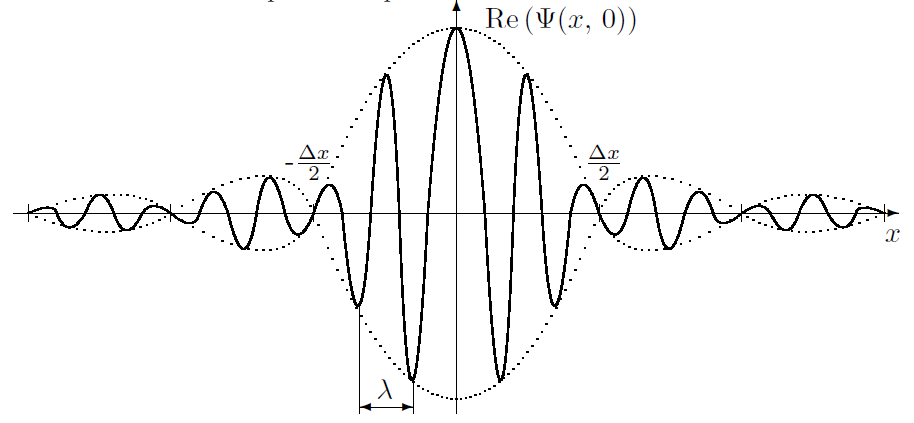

Для длины волны имеем


$$\lambda =\frac{2\pi \hbar }{p_0 }<<\frac{2\pi \hbar }{\Delta p}\equiv \Delta x,\;т\ldotp к\ldotp \Delta p<<p_0$$


Частица локализована в области с шириной $\Delta x=$$\frac{2\pi \hbar }{\Delta p}$ с центром в точке $x_0 ={\left(\frac{d}{\textrm{d}p}E\right)}_0 t$

Таким образом, справедливо


$$\Delta x\;\Delta p\simeq 2\pi \hbar$$


Групповая скорость волны


$$v_{\mathrm{gr}} ={\left(\frac{d}{\textrm{d}p}E\right)}_0$$


Групповая скорость волны совпадает со скоростью частицы v как в нерелятивистском случае

$E=\frac{p^2 }{2m}$ => $v_{\mathrm{gr}} =\frac{p}{m}=v$

так и в релятивистском случае

$E=\sqrt{p^2 c^2 +m^2 c^4 }$  =>  $v_{\mathrm{gr}} =\frac{c^2 p}{\sqrt{p^2 c^2 +m^2 c^4 }}=\frac{c^2 p}{E}=v$

**Замечание.** В области локализации частицы волновая функция хорошо апроксимируется волной де Бройля.

## 2.2. Свойства [волн де Бройля](https://ru.wikipedia.org/wiki/Волны_де_Бройля)

syms hp p p1 E E1 x t
assume(hp>0)
Psi_p(x,t)=1/sqrt(2*pi*hp)*exp(i*(p*x-E*t)/hp)

$$Psi\_p(x, t) = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}-p\,x\,\mathrm{i}}{\mathrm{hp}}}}{2\,\sqrt{\mathrm{hp}}\,\sqrt{\pi }}$$

Psi_p1(x,t)=1/sqrt(2*pi*hp)*exp(i*(p1*x-E1*t)/hp)

$$Psi\_p1(x, t) = \frac{\sqrt{2}\,{\mathrm{e}}^{-\frac{E_{1}\,t\,\mathrm{i}-p_{1}\,x\,\mathrm{i}}{\mathrm{hp}}}}{2\,\sqrt{\mathrm{hp}}\,\sqrt{\pi }}$$

I=simplify(int(Psi_p1'*Psi_p,x,-inf,inf))

$$I(t) = \begin{array}{l} \frac{{\mathrm{e}}^{-\frac{\text{E}\,t\,\mathrm{i}}{\mathrm{hp}}}\,\left({\mathrm{e}}^{\frac{\bar{E_{1}}\,\bar{t}\,\mathrm{i}}{\mathrm{hp}}}\,\left(\lim_{x\to -\infty }\sigma_{1}\right)\,\mathrm{i}-{\mathrm{e}}^{\frac{\bar{E_{1}}\,\bar{t}\,\mathrm{i}}{\mathrm{hp}}}\,\left(\lim_{x\to \infty }\sigma_{1}\right)\,\mathrm{i}\right)}{2\,\pi \,\left(p-\bar{p_{1}}\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{p\,x\,\mathrm{i}}{\mathrm{hp}}}\,{\mathrm{e}}^{-\frac{x\,\bar{p_{1}}\,\mathrm{i}}{\mathrm{hp}}} \end{array}$$

I=dirac(p-p1)

$$I = \delta (p-p_{1})$$

Этот результат называется условием нормировки волн де Бройля на $\delta$-функцию


$$\int_{-\infty }^{+\infty } \Psi_{p^{\prime } }^* \left(x,t\right)\Psi_p \left(x,t\right)\mathrm{dx}=\delta \left(p-p^{\prime } \right)$$


Аналогично, в силу того что p и х входят в волну де Бройля симметрично, справедливо


$$\int_{-\infty }^{+\infty } \Psi_p^* \left(x^{\prime } ,t\right)\Psi_p \left(x,t\right)\mathrm{dx}=\delta \left(x-x^{\prime } \right)$$
